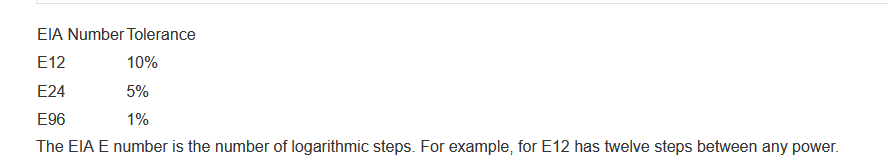

% Compute balance resistor
if HVBUS.R_balance == -1
    % Set max voltage across each bus capacitor to 90% of rated voltage
    Vmax_target = HVBUS.VDC_cap*0.9;

    % Compute balance resistor acroess each capacitor
    R_balance_nom = computeBalanceResistor(Vmax_target, HVBUS.Vbus, HVBUS.Cap*HVBUS.Np_cap, HVBUS.Ns_cap);  % Ohms
    HVBUS.R_balance = round63(R_balance_nom, 'E96', 'arithmetic');
end

% Compute maximum voltage seen be each capacitor 
Vmax = computeVbusCapVmax(HVBUS.R_balance, HVBUS.Vbus, HVBUS.Cap, 2);

% Check if max capacitor voltage exceeds rating
if Vmax >= HVBUS.VDC_cap
    error("Voltage across bus capacitor exceeds voltage rating: %0.2f >= %0.2f VDC",Vmax, HVBUS.VDC_cap);
end


## Calculating Vbus Capacitor Ripple and RMS Current

[Source](https://kaizerpowerelectronics.dk/tesla-coils/drsstc-design-guide/dc-bus-capacitor/)

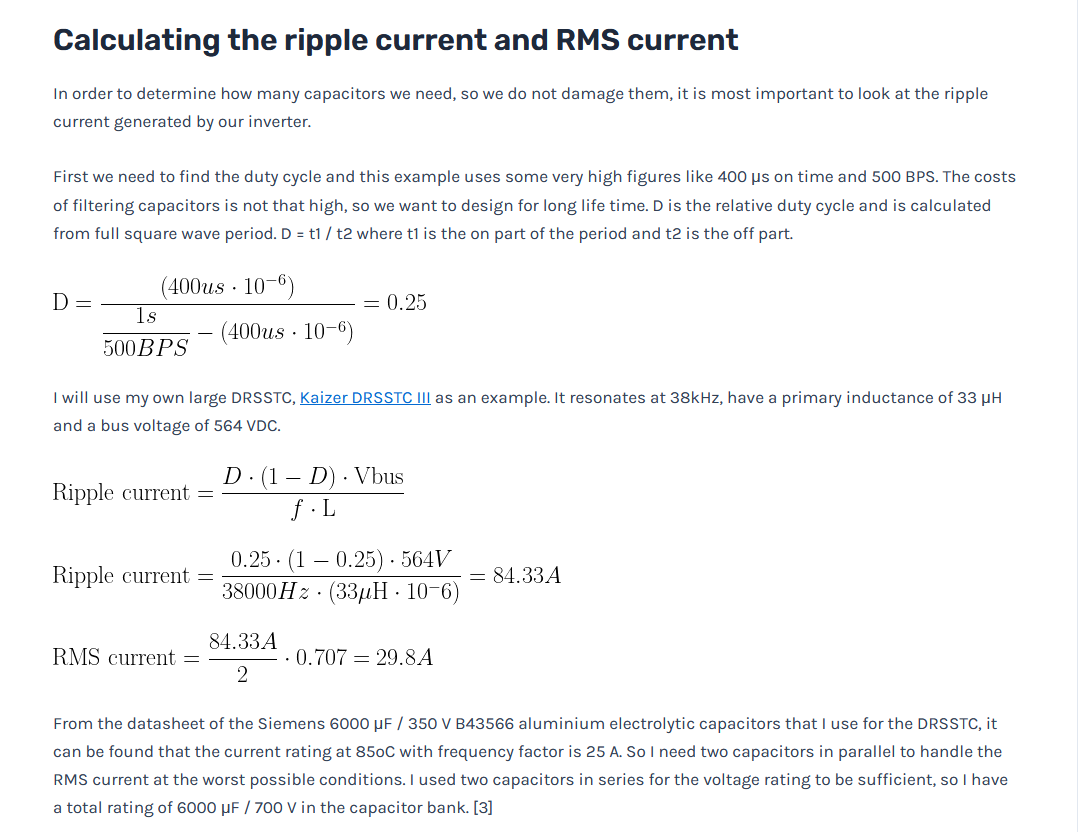

% Compute worst-case ripple current (Ipk2pk) for max duty cycle
DC_max = SYSTEM.PRF_DC_max/100;
HVBUS.I_pk2pk_cap = (DC_max*(1-DC_max)*HVBUS.Vbus)/(SYSTEM.F_res_pri*PRI_TANK.Lp); % A_pk2pk
HVBUS.I_pk_cap = HVBUS.I_pk2pk_cap/2;       % peak capacitor current, Apk
HVBUS.I_rms_cap = HVBUS.I_pk_cap/sqrt(2);   % capacitor RMS current, Arms

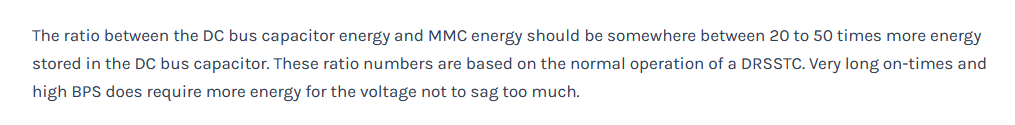

% Compute ratio between energy stored in VBUS caps and the energy needed
% (and therefore stored w/in MMC bank) for each bang (1 PRF cycle)
energyRatio = HVBUS.E_bus/MMC_BANK.Bank_bangEnergy;

if energyRatio < 20
    warning("Voltage bus to bang energy ratio is low (%0.2f), 20 to 50 recommended.",energyRatio);
end


% Check if ripple current rating is violated for mm
if HVBUS.I_pk2pk_cap >= HVBUS.Iripple_cap_rating
    warning("Bus voltage capacitor ripple current exceeds rating: %0.2f >= %0.2f Apk2pk",HVBUS.I_pk2pk_cap,HVBUS.Iripple_cap_rating);
end


% Compute voltage droop on Vbus due to bang energy consumption

% Compute energy in voltage bus capacitors after bang
E_f = HVBUS.E_bus - MMC_BANK.Bank_bangEnergy;   % J
% Compute voltage on bus capacitor bank after bang
V_c = sqrt((2*(E_f))/HVBUS.Cap_eq);     % V
% Voltage droop on voltage bus
Vdroop = HVBUS.Vbus - V_c;

% Percent of voltage bus sag/droop after each bang
Vdroop_percent = (Vdroop/HVBUS.Vbus)*100;  % %


## Managing In-Rush Current

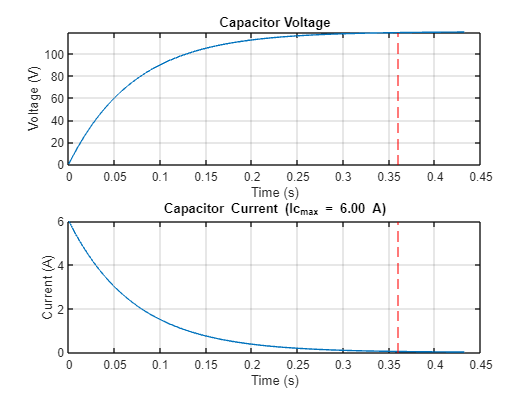

HV Bus bleed resistor: 0.55 kOhm



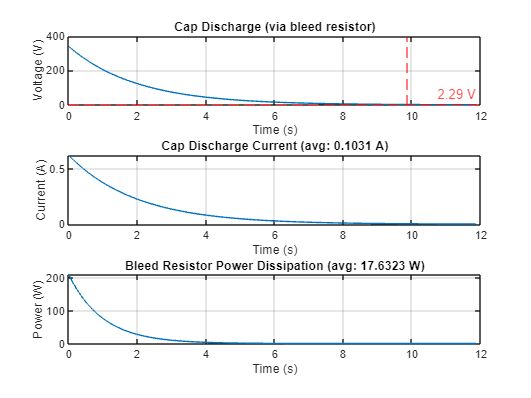

VBUS_INRUSH_CURRENT

#### Print Results

fprintf("\n\n################ Vbus Params BEGIN ##########################\n\n")



################ Vbus Params BEGIN ##########################



fprintf("Bus Voltage: %0.2f V\n\n", HVBUS.Vbus);

Bus Voltage: 339.41 V



fprintf("Balance resistor: %0.2f (actual) %0.4f (nom.) kOhm\n\n", HVBUS.R_balance/1e3,R_balance_nom/1e3);

Balance resistor: 60.40 (actual) 60.3380 (nom.) kOhm



fprintf("Max voltage across each capacitor: %0.2f V\n\n", Vmax);

Max voltage across each capacitor: 225.06 V



fprintf("Voltage droop on bus after 1 PRF cycle (bang): %0.2f %%\n\n", Vdroop_percent);

Voltage droop on bus after 1 PRF cycle (bang): 19.21 %



fprintf("Bus capacitor bank safe discharge time through balance resistors: %0.4f sec\n\n", HVBUS.SafeDischargeTime_balance);

Bus capacitor bank safe discharge time through balance resistors: 2174.4000 sec



fprintf("Equivalent bus capacitance: %0.2f uF\n\n", HVBUS.Cap_eq * 1e6);

Equivalent bus capacitance: 1800.00 uF



fprintf("Bulk capacitance configuration: %d parallel branch(es) w/ %d cap(s) in series per branch\n\n", HVBUS.Np_cap, HVBUS.Ns_cap);

Bulk capacitance configuration: 1 parallel branch(es) w/ 2 cap(s) in series per branch



fprintf("################ VBus Params END ##########################\n\n")

################ VBus Params END ##########################

